# IEEE LAT AM T

# Generation and Transmission Expansion Planning with Full-year Hourly Power Balance

#### By Thiago José da Luz, https://orcid.org/0000-0002-6018-9429

email: thiagojluz@ufpr.br

Date: 12/05/2023

**To solve is necessary Gurobi toolbox**

clear all;
clc;
m = 1e-3; % factor to decrease the number size
k = 1e-6; % factor to decrease the number size
horas = 8760; % hours in a year
sub = 4; % number of nodes
run dados_v5_CO2_Def.mlx; % load data
tec = ["solar", "eolica", "biomassa", "bagaco", "biogas" "biogas_RU", "pch"]; ...
    % technologies ("solar", "wind", "biomass", "Sugarcane", "biogas" ...
% "Urban waste", "SHP")

UHE_flex = ["maranhao" "mirador" "BQ" "formoso"]; % ReS
UHE_fio = ["apertados" "SA" "itapiranga" "saudade" "TB" "parana" ...
    "itaguacu" "PG" "jatoba" "tabajara" "castanheira"]; % RoR

termicas = ["carvao" "gncc" "gnca" "nu"]; % "coal" "CCGT" "OCGT" "nuclear"

aux = [];
for t = 1:length(UHE_flex)
    if sub_UHEf.(UHE_flex(t)) > sub % check if it belongs to the node
        aux = [aux t];                               
    end
end
UHE_flex(aux) = [];

aux = [];
for t = 1:length(UHE_fio)
    if sub_UHEfio.(UHE_fio(t)) > sub % check if it belongs to the node
        aux = [aux t];                               
    end
end
UHE_fio(aux) = [];
clear t  aux

## Objective function

nt = length(tec); % number of non-dispatchable renewable energy
nUHEf = length(UHE_flex); % number of ReS
nUHEfio = length(UHE_fio);% number of RoR
nTer = length(termicas); % number of non-renewable
C_inva = [];
txa = [];
lifea = [];
C_anoa = [];
for t = 1:nt % non-dispatchable renewable cost
    C_inva = [C_inva custo_subsistema(C_inv.(tec(t)),sub)];
    txa = [txa custo_subsistema(tx.(tec(t)),sub)];
    lifea = [lifea custo_subsistema(life.(tec(t)),sub)];
    C_anoa = [C_anoa custo_subsistema(C_ano.(tec(t)),sub)];
end

for t = 1:nTer % non-renewable cost
    C_inva = [C_inva custo_subsistema(C_inv.(termicas(t)),sub)];
    txa = [txa custo_subsistema(tx.(termicas(t)),sub)];
    lifea = [lifea custo_subsistema(life.(termicas(t)),sub)];
    C_anoa = [C_anoa custo_subsistema(C_ano.(termicas(t)),sub)];
end


tx_l = custo_subsistema(tx_l,length(custo_linha)); % transmission cost
life_l = custo_subsistema(life_l,length(custo_linha));
C_l_ano = custo_subsistema(0,length(custo_linha));

%%%%%%%%%%%%%%
% ReS cost
C_inv_uhe = [];
tx_uhe = [];
life_uhe = [];
C_ano_uhe = [];
for t = 1:nUHEf
    C_inv_uhe = [C_inv_uhe (C_inv_UHEf.(UHE_flex(t))*cap_UHEf.(UHE_flex(t)))];
    tx_uhe = [tx_uhe tx_UHEf.(UHE_flex(t))];
    life_uhe = [life_uhe life_UHEf.(UHE_flex(t))];
    C_ano_uhe = [C_ano_uhe (C_ano_UHEf.(UHE_flex(t))*cap_UHEf.(UHE_flex(t)))];
end
%%%%%%%%%%%%%%
% RoR cost
C_inv_uhe_fio = [];
tx_uhe_fio = [];
life_uhe_fio = [];
C_ano_uhe_fio = [];
for t = 1:nUHEfio
    C_inv_uhe_fio = [C_inv_uhe_fio (C_inv_UHEfio.(UHE_fio(t))*cap_UHEfio.(UHE_fio(t)))];
    tx_uhe_fio = [tx_uhe_fio tx_UHEfio.(UHE_fio(t))];
    life_uhe_fio = [life_uhe_fio life_UHEfio.(UHE_fio(t))];
    C_ano_uhe_fio = [C_ano_uhe_fio (C_ano_UHEfio.(UHE_fio(t))*cap_UHEfio.(UHE_fio(t)))];
end
%%%%%%%%%%%%%%
% operating costs of non-renewable
C_OMa = [];
for t=1:nTer    
    C_OMaux((1:sub*horas),1) = C_OM.(termicas(t));
    C_OMa = [C_OMa; C_OMaux];
end

%%%%%%%%%%%%%%
clear C_inv tx life C_ano C_OMaux C_OM
% CAPEX
C_inv = [C_inva C_inv_uhe C_inv_uhe_fio custo_linha'];
tx = [txa tx_uhe tx_uhe_fio tx_l];
life = [lifea life_uhe life_uhe_fio life_l];
C_ano = [C_anoa C_ano_uhe C_ano_uhe_fio C_l_ano];

% annualized investment costs
i = length(C_inv); 
custo = zeros(i,1);
for t = 1:i
    [custo(t)] = custo_anualizado(tx(t),life(t),C_inv(t), C_ano(t));
end

dfh = C_defh*ones(horas*sub,1); % deficit
curt = C_curt*ones(horas*sub,1); % curtaiment

fx0 = sparse(horas*(sub^2),1); % transmission power flow 
UHEf0 = sparse(horas*sub,1); % hydropower generation (ReS)
UHEfio0 = UHEf0; % hydropower generation (RoR)
f = sparse([custo; fx0; C_def; dfh; curt; UHEf0; UHEfio0; C_OMa]);...
    % objective function (Eq. 1)

clear C_inva txa lifea C_anoa t i custo_linha tx life C_inv C_ano tx_l life_l custo ...
    C_l_ano C_defh dfh C_def C_curt curt C_inv_uhe tx_uhe life_uhe C_ano_uhe...
    C_inv_UHEf tx_UHEf life_UHEf C_ano_UHEf C_inv_uhe_fio tx_uhe_fio...
    life_uhe_fio C_ano_uhe_fio UHEfio0 fx0 C_OMa C_OMbat C_OMbat0

# Equations of Equalities 

## Energy Balance:

PLT0 = zeros(1, nl); 
PUHEf0 = zeros(1,nUHEf);
PUHEfio0 = zeros(1,nUHEfio);
PT0 = zeros(1,nTer*sub);
nv =length(f); 
Aeq1 = sparse(horas*sub,nv); 
i = 1:sub;
j = i;
t = 1;
for t1 = 1:sub % loop by node
    p_LT = zeros(1,(sub^2)); % transmission power flow 
    t2 = 1;
    for taux1 = 1:sub  
        for taux2 = 1:sub         
            if i(taux1)==t1 || j(taux2)==t1           
                if i(taux1)==t1 && i(taux1)~=j(taux2) 
                    p_LT(t2) = -1;
                elseif j(taux2)==t1 && i(taux1)~=j(taux2)
                       p_LT(t2) = (1-pl);
                end                
            end
            t2 = t2 + 1;
        end       
    end

    for t3=1:horas  % loop for hours
        gh = UHEf0'; 
        taux = t3 + ((t1-1)*horas);
        gh(taux) = 1;
    
        aux3 = sparse(horas,(sub^2)); 
        aux3(t3,:) = p_LT;
        aux3 = aux3';
        aux3 = reshape(aux3,1,[]); 
        fc0 = zeros(nt,sub);
        for t4 = 1:nt
            fc0(t4,t1) = fc.(tec(t4))(t3,t1);
        end
        LT = aux3; 
        Cdef = 0; 
        def = gh;
        curt = -gh;
        G_UHEf = gh; 
        G_UHEfio = gh;        
        GT = [];
        for t5=1:nTer    
            GT = [GT gh];
        end
        
        fc0 = reshape(fc0',1,[]); 
        % Energy balance (Eq. 13)
        Aeq1(t,:) = [fc0 PT0 PUHEf0 PUHEfio0 PLT0 LT Cdef def...
            curt G_UHEf G_UHEfio GT];
        t = t + 1;
    end
end

Aeq1 = -Aeq1;
b1_aux = reshape(carga,[],1); 
proda = zeros(horas*sub,nt);
for t = 1:nt
    proda(:,t) = reshape(prod.(tec(t)),[],1);
end

proda = sum(proda,2); 
autoproda = reshape(autoprod,[],1);
GD_proda = reshape(prod.GD,[],1); % DPV
beq1 = -(b1_aux - proda - autoproda - GD_proda);
clear gh p_LT aux3 t t1 t2 t3 t4 taux fc0 i j taux1 taux2 ....
    b1_aux proda autoproda GD_proda LT Cdef def curt G_UHEf ...
    G_UHEfio t5 GT G_PSH PT0 PUHEf0 PUHEfio0 PLT0 P_psh0 P_bat0 G_Bat

## Run-of-river power generation (Eq. 15)

dia = 24;
if horas>dia
    aux = horas - dia + 1;
    mat = ones(aux,horas);
    mat = triu(mat);
    mat = tril(mat,(dia-1));
    G_UHEfio = sparse((aux*sub),(horas*sub));
    PUHEfio = sparse((aux*sub),nUHEfio);
    beq2 = zeros((aux*sub),1);
    for t = 1:sub
        L1 = aux*(t-1) + 1;
        L2 = aux*t;
        C1 = horas*(t-1) + 1;
        C2 = horas*t;
        G_UHEfio((L1:L2),(C1:C2)) = mat;
        t3 = 1;
        for t1 = L1:L2
            for t2 = 1:nUHEfio    
                if sub_UHEfio.(UHE_fio(t2)) == t 
                    PUHEfio(t1,t2) = -cap_UHEfio.(UHE_fio(t2))*...
                        sum(fc.UHEfio(t3:(t3+dia-1),t));               
                end
            end
            beq2(t1,1) = cap.UHEfio(t)*sum(fc.UHEfio(t3:(t3+dia-1),t));
            t3 = t3 + 1;
        end
        
    end
    P0 = sparse((aux*sub), sub*nt); 
    PT0 = sparse((aux*sub), sub*nTer); 
    PUHEf0 = sparse((aux*sub),nUHEf);
    PLT0 = zeros((aux*sub), nl); 
    fx0 = sparse((aux*sub), horas*(sub^2)); 
    P0_def = sparse((aux*sub),(horas*sub + 1)); 
    P0_curt = sparse((aux*sub),(horas*sub)); 
    UHEf0 = sparse((aux*sub), (horas*sub)); 
    GT0 = [];
    for t5=1:nTer    
        GT0 = [GT0 UHEf0];
    end
    Aeq2 = [P0 PT0 PUHEf0 PUHEfio PLT0 fx0 P0_def P0_curt ...
        UHEf0 G_UHEfio GT0];
else
    G_UHEfio = sparse(sub,(horas*sub));
    PUHEfio = sparse(sub,nUHEfio);
    beq2 = zeros(sub,1);
    for t = 1:sub
        t1 = horas*(t-1)+1;
        t2 = horas*t;
        G_UHEfio(t,(t1:t2)) = 1;
        
        for t3 = 1:nUHEfio   
                if sub_UHEfio.(UHE_fio(t3)) == t 
                    PUHEfio(t,t3) = -cap_UHEfio.(UHE_fio(t3))*...
                        sum(fc.UHEfio(1:horas,t));               
                end
        end
        beq2(t,1) = cap.UHEfio(t)*sum(fc.UHEfio(1:horas,t));        
    end 
    P0 = sparse(sub, sub*nt); 
    PT0 = sparse(sub, sub*nTer); 
    PUHEf0 = sparse(sub,nUHEf); 
    PLT0 = zeros(sub, nl);
    fx0 = sparse(sub, horas*(sub^2)); 
    P0_def = sparse(sub,(horas*sub + 1)); 
    P0_curt = sparse(sub,(horas*sub));
    UHEf0 = sparse(sub, (horas*sub));
    GT0 = [];
    for t5=1:nTer    
        GT0 = [GT0 UHEf0];
    end
    Aeq2 = [P0 PT0 PUHEf0 PUHEfio PLT0 fx0 P0_def P0_curt ...
        UHEf0 G_UHEfio GT0];
end

clear dia aux mat G_UHEfio PUHEfio t L1 L2 C1 C2 t3 t1 t2 P0 PUHEf0...
    PLT0 fx0 P0_def P0_curt UHEf0 GT0 t5 P_psh0 G_PSH0 G_Bat0 P_bat0

# Equations of Inequalities 

## Transmission power flow (Eq. 25)

P0 = sparse(1, sub*nt);
PT0 = zeros(1,nTer*sub); 
PUHEf0 = sparse(1,nUHEf);
PUHEfio0 = sparse(1,nUHEfio); 
P0_def = sparse(1,(horas*sub + 1));
P0_curt = sparse(1,horas*sub); 
UHEf0 = sparse(1, (horas*sub)); 
GT0 = [];
for t=1:nTer    
    GT0 = [GT0 UHEf0];
end
A1 = sparse((sub^2)*horas, nv);
b1 = zeros((sub^2)*horas, 1);
ubI = b1;
cont = 0;
t1 = 0;
ip = [];
jp = [];
while cont < nl
    t1 = t1 + 1;
    for t = t1:(sub-1)
        ip = [ip t1];
        jp = [jp (t+1)];
    end
    cont = cont + 1;
end
i = [];
j = [];
for t1 = 1:sub
    for t2 = 1:sub
        i = [i t1];
        j = [j t2];
    end    
end
fx = string(ip);
p_LT = string(jp);
pl_sub_p = fx+p_LT;
pl_sub_p = str2double(pl_sub_p);
pl_sub_n = p_LT+fx;
pl_sub_n = str2double(pl_sub_n);
fx = string(i);
p_LT = string(j);
fl_sub = fx+p_LT;
fl_sub = str2double(fl_sub);

t = 1;
for t1 = 1:sub^2     
    for t2 = t1:sub^2:((sub^2)*horas)
        fx = sparse(1,((sub^2)*horas)); 
        p_LT = zeros(1, nl); 
        fx(t2) = 1;
        if i(t1)~=j(t1)           
            pos = find(pl_sub_p==fl_sub(t1) | pl_sub_n==fl_sub(t1) );
            p_LT(pos)=-1;
            b1(t) = cap_linha(pos);
            ubI(t2) = max_linha(pos);
        end
        A1(t,:) = [P0 PT0 PUHEf0 PUHEfio0 p_LT fx P0_def P0_curt ...
            UHEf0 UHEf0 GT0];
        t = t+1;
    end
end
clear cont pos t t1 t2 fx  p_LT pl_sub_n fl_sub pl_sub_p cap_linha pl

## Deficit (Eq. 27)

m_def = speye(horas*sub);
Cdef = -1;
PLT0 = zeros(1, nl); 
fx0 = sparse(1, horas*(sub^2)); 
A2 = sparse(horas*sub,nv);
b2 = zeros(horas*sub,1);
for t = 1:horas*sub
    A2(t,:) = [P0 PT0 PUHEf0 PUHEfio0 PLT0 fx0 Cdef m_def(t,:) P0_curt ...
        UHEf0 UHEf0 GT0];
end
clear Cdef m_def Cdef

## Hidropower with large reservoir (ReS) 

A3a = sparse(horas*sub , nv);
A3b = A3a; 
A3c = A3a; 
A3d = A3a; 
b3a = zeros(horas*sub,1);
b3b = b3a;
b3c = b3a;
b3d = b3a;
t = 1;
for t1 = 1:sub
    PUHEfa = zeros(1,nUHEf); 
    PUHEfb = zeros(1,nUHEf);
    PUHEfioa = zeros(1,nUHEfio);
    PUHEfiob = zeros(1,nUHEfio); 
    
    for t3 = 1:nUHEf     
        if sub_UHEf.(UHE_flex(t3)) == t1 
            PUHEfa(t3) = -cap_UHEf.(UHE_flex(t3));
            PUHEfb(t3) = cap_UHEf.(UHE_flex(t3))*cap.UHEf_min(t1);
        end
    end
    
    for t3 = 1:nUHEfio      
        if sub_UHEfio.(UHE_fio(t3)) == t1 
            PUHEfioa(t3) = -cap_UHEfio.(UHE_fio(t3));
            PUHEfiob(t3) = cap_UHEfio.(UHE_fio(t3))*cap.UHEfio_min(t1);
        end
    end
    
    for t2=1:horas 
        gh = UHEf0; 
        taux = t2 + ((t1-1)*horas);
        gh(taux) = 1;
        G_UHEf = gh; 
        G_UHEfio = gh; 
        
        A3a(t,:) = [P0 PT0 PUHEfa PUHEfio0 PLT0 fx0 P0_def P0_curt ...
            G_UHEf UHEf0 GT0];
        b3a(t) = cap.UHEf(t1);
        A3b(t,:) = [P0 PT0 PUHEfb PUHEfio0 PLT0 fx0 P0_def P0_curt ...
            -G_UHEf UHEf0 GT0 ];
        b3b(t) = -cap.UHEf(t1)*cap.UHEf_min(t1);
        
        A3c(t,:) = [P0 PT0 PUHEf0 PUHEfioa PLT0 fx0 P0_def P0_curt UHEf0 ...
            G_UHEfio GT0 ];
        b3c(t) = cap.UHEfio(t1);
        A3d(t,:) = [P0 PT0 PUHEf0 PUHEfiob PLT0 fx0 P0_def P0_curt UHEf0 ...
            -G_UHEfio GT0];
        b3d(t) = -b3c(t)*cap.UHEfio_min(t1);
        
        t = t+1;
    end
end
A3 = [A3a; A3b; A3c; A3d]; 
b3 = [b3a; b3b; b3c; b3d];
clear t t1 t2 t3 PUHEfa gh G_UHEf PUHEfb A3a A3b b3a b3b G_UHEfio A3c A3d b3c b3d...
    PUHEfioa PUHEfiob taux

## Hidropower with large reservoir (ReS)   (Eq. 20)

A4a = sparse(sub , nv); 
b4a = zeros(sub,1);
auxa = sum(fc.UHEf);
A4b = sparse(sub , nv);
b4b = zeros(sub,1);
auxb = sum(fc.UHEfio);

for t = 1:sub
    PUHEfa = zeros(1,nUHEf);
    GHauxa = UHEf0; 
    PUHEfb = zeros(1,nUHEfio);
    GHauxb = UHEf0; 
        
    t1 = 1 + ((t-1)*horas);
    t2 = horas*t;
    GHauxa(t1:t2) = 1;
    GHauxb(t1:t2) = 1;
     
    for t3 = 1:nUHEf         
        if sub_UHEf.(UHE_flex(t3)) == t 
            PUHEfa(t3) = -cap_UHEf.(UHE_flex(t3));
        end
    end
    for t3 = 1:nUHEfio        
        if sub_UHEfio.(UHE_fio(t3)) == t 
            PUHEfb(t3) = -cap_UHEfio.(UHE_fio(t3));
        end
    end
        
    PUHEfa = auxa(t)*PUHEfa; 
    PUHEfb = auxb(t)*PUHEfb; 
    
    A4a(t,:) = [P0 PT0 PUHEfa PUHEfio0 PLT0 fx0 P0_def P0_curt ...
        GHauxa UHEf0 GT0];
    b4a(t) = auxa(t)*cap.UHEf(t); 
end
A4 = [A4a; ]*k; % factor to decrease the number size
b4 = [b4a; ]*k; 

clear t t1 t2 t3 GHaux PUHEf auxa P0 PUHEfio0 PLT0 UHEf0 PUHEf0 A4a A4b b4a b4b ...
    P_psh0 G_PSH0 G_Bat0 P_bat0

## Hidropower with large reservoir (ReS)   

## Storage constraint  (Eq. 17)

A5a = sparse(sub*horas , nv); 
b5a = sparse(horas*sub,1);
A5b = A5a; 
b5b = b5a;
UHEh1 = ones(horas);
UHEh1 = tril(UHEh1);

for t = 1:sub   
    PUHEf = zeros(horas,nUHEf);
    STO_inst = zeros(1,nUHEf);
    STO_inst_min = STO_inst;
    UHEf_inst_T0 = STO_inst;
    C_aux1 = nv-(horas*sub)-(horas*sub*nTer)-(horas*(sub-t+1))+1;        
    C_aux2 = C_aux1 + horas - 1;
    L_aux1 = (t-1)*horas + 1;
    L_aux2 = L_aux1 + horas - 1;
    A5a((L_aux1:L_aux2),(C_aux1:C_aux2)) = -UHEh1; 
    A5b((L_aux1:L_aux2),(C_aux1:C_aux2)) = UHEh1; 
    
    for t1 = 1:nUHEf  
        if sub_UHEf.(UHE_flex(t1)) == t 
            PUHEf(:,t1) = UHEh1*fc.UHEf(:,t)*cap_UHEf.(UHE_flex(t1)); 
            STO_inst(t1) = sto.(UHE_flex(t1));
            UHEf_inst_T0(t1) = STO_inst(t1)*sto.UHEf_T0(t);
            STO_inst_min(t1) = STO_inst(t1)*(sto.UHEf_min(t));
        end
    end
    C_aux1 = nt*sub + nTer*sub + 1; 
    C_aux2 = C_aux1 + nUHEf - 1;
    A5a((L_aux1:L_aux2),(C_aux1:C_aux2)) = PUHEf - STO_inst + UHEf_inst_T0;
    A5b((L_aux1:L_aux2),(C_aux1:C_aux2)) = -PUHEf + STO_inst_min - UHEf_inst_T0;
    
    UHEnat = UHEh1*fc.UHEf(:,t)*cap.UHEf(t); 
    UHEf_T0 = sto.UHEf_T0(t)*sto.UHEf(t); 
    b5a(L_aux1:L_aux2) = sto.UHEf(t) - UHEnat - UHEf_T0; 
    b5b(L_aux1:L_aux2) = -(sto.UHEf_min(t)*sto.UHEf(t)) + UHEnat + UHEf_T0;
end
A5 = [A5a; A5b]*k;
b5 = [b5a; b5b]*k;

clear UHEh1 PUHEf STO_inst L_aux1 L_aux2 C_aux1 C_aux2 UHEnat UHEf_T0 ...
    A5a A5b b5a b5b STO_inst_min t t1 GT0

## Thermal power (Eq. 24)

b6 = zeros(horas*sub*nTer,1);
GT = speye(horas*sub*nTer);
PTE = zeros(horas*sub*nTer, nTer*sub);

t1 = 1;
t2 = horas;
t4 = 1;
for t=1:nTer
    for t3 = 1:sub
        PTE(t1:t2,t4) = -1;
        b6(t1:t2) = cap.(termicas(t))(t3);
        t1 = t2 + 1;
        t2 = t2 + horas;
        t4 = t4 + 1;
    end
end
P0 = sparse(horas*sub*nTer, sub*nt); 
PUHEf0 = sparse(horas*sub*nTer,nUHEf); 
PUHEfio0 = sparse(horas*sub*nTer,nUHEfio); 
PLT0 = sparse(horas*sub*nTer, nl); 
fx0 = sparse(horas*sub*nTer, horas*(sub^2)); 
P0_def = sparse(horas*sub*nTer,(horas*sub + 1)); 
P0_curt = sparse(horas*sub*nTer,horas*sub);
UHEf0 = sparse(horas*sub*nTer, (horas*sub)); 

A6 = [P0 PTE PUHEf0 PUHEfio0 PLT0 fx0 P0_def P0_curt UHEf0 ...
    UHEf0 GT];
clear P0 PTE PUHEf0 PUHEfio0 PLT0 fx0 P0_def P0_curt UHEf0 UHEf0 GT t ...
    t1 t2 P_psh0 G_PSH0 G_Bat0 P_bat0

## Matrix A

A = [A1; A2; A3; A4; A5; A6;];
b = full([b1; b2; b3; b4; b5; b6;]);
clear A1 b1 A2 b2 A3 A4 b3 b4 A5 b5 A6 b6 A7 A8 b7 b8 A9 A10 b9 b10

## Matrix Aeq

Aeq = [Aeq1; Aeq2];
beq = full([beq1; beq2]);
clear Aeq1 beq1 Aeq2 beq2

# Bound Constraints

## Lower Bound

lb_tec = [];
for t = 1:nt
    lb_tec = [lb_tec; Min.(tec(t))]; 
end

lb_term = [];
for t = 1:nTer
    lb_term = [lb_term; Min.(termicas(t))];
end

lb_UHEf = zeros(nUHEf,1); 
lb_UHEfio = zeros(nUHEfio,1);
lb_UHEf_h = zeros(sub*horas,1); 
lb_UHEfio_h = lb_UHEf_h; 

lbPI = min_linha;
fx0 = sparse(1, horas*(sub^2));
lbI = fx0';

lbT = zeros(nTer*horas*sub,1); 

P0_def = sparse(1,(horas*sub + 1)); 
P0_curt = sparse(1,horas*sub);

lb = [lb_tec; lb_term; lb_UHEf; lb_UHEfio; lbPI; lbI; P0_def'; P0_curt'; ...
    lb_UHEf_h; lb_UHEfio_h; lbT;];
lb = full(lb);
clear lbW  lbPI lbI fx0 PLT0 min_w min_linha lbS min_s P0_def P0_curt min_linha...
    lb_tec Min lb_UHEf lb_UHEf_h lb_UHEfio lb_UHEfio_h lbT lb_term lb_psh lb_PSH t1 t2

## Upper Bound

ub_tec = [];
for t = 1:nt
    ub_tec = [ub_tec; Max.(tec(t))]; 
end

ub_term = [];
aux = [];
for t = 1:nTer
    ub_term = [ub_term; Max.(termicas(t))]; 
    aux = [aux; cap.(termicas(t))];
end


ubPI = max_linha; 
ub_def = Max.def*ones((horas*sub + 1),1);
ub_curt = Max.curt*ones(horas*sub,1); 

ub_UHEf = ones(nUHEf,1);
ub_UHEfio = ones(nUHEfio,1); 
ub_UHEf_h = ones(sub*horas,1)*max(cap.UHEf)*5; 
ub_UHEfio_h = ones(sub*horas,1)*max(cap.UHEfio)*5; 

ub_T = ones(nTer*horas*sub,1)*max(aux); 


ub = [ub_tec; ub_term; ub_UHEf; ub_UHEfio; ubPI; ubI; ub_def; ub_curt; ...
    ub_UHEf_h; ub_UHEfio_h; ub_T;];

ub = full(ub);
clear ubI ubPI max_w max_linha ubS max_s ub_tec t Max max_linha Max ub_def ub_curt...
    ub_UHEf ub_UHEf_h ub_UHEfio ub_UHEfio_h ub_term aux

## Solve MILP problem

t1 = nt*sub + nTer*sub + 1; 
t2 = t1 + nUHEf + nUHEfio - 1;
int = t1:t2; 
f = f*k; % factor

% GUROBI
model.obj = full(f);
model.A = [sparse(A); sparse(Aeq)];
n = size(model.A, 2);
model.vtype = repmat('C', n, 1);
model.vtype(int) = 'B';
model.sense = [repmat('<',size(A,1),1); repmat('=',size(Aeq,1),1)];
model.rhs = full([b(:); beq(:)]);
model.lb = lb;
model.ub = ub;

params.NodefileStart = 0.5; 
params.Threads = 1;


clearvars -except model horas sub tec teca UHE_flex UHE_fio ...
    termicas params;
tic
result = gurobi(model,params);

Set parameter Username
Set parameter NodefileStart to value 0.5
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2022-07-23
Gurobi Optimizer version 9.5.0 build v9.5.0rc5 (win64)
Thread count: 4 physical cores, 8 logical processors, using up to 1 threads
Optimize a model with 595592 rows, 420546 columns and 309716401 nonzeros
Model fingerprint: 0x3b223647
Variable types: 420531 continuous, 15 integer (15 binary)
Coefficient statistics:
  Matrix range     [1e-08, 3e+01]
  Objective range  [4e-02, 8e+03]
  Bounds range     [8e-01, 1e+07]
  RHS range        [9e-07, 5e+02]
Presolve removed 0 rows and 0 columns (presolve time = 328s) ...
Presolve removed 0 rows and 0 columns (presolve time = 514s) ...
Presolve removed 0 rows and 0 columns (presolve time = 638s) ...
Presolve removed 0 rows and 70093 columns (presolve time = 1649s) ...
Presolve removed 89859 rows and 70093 columns (presolve time = 1765s) ...
Presolve removed 89859 rows and 70093 column

result.status

ans = 'OPTIMAL'

tempSim = toc/(60*60)

tempSim = 6.7494

clear model
save("x_s_BAT_CO2_Def_v2")

clear all
m = 1; % factor
load('x_s_BAT_CO2_Def_v2');
run dados_v5_CO2_Def.mlx;
nt = length(tec);
nUHEf = length(UHE_flex);
nUHEfio = length(UHE_fio);
nTer = length(termicas);
m = 1e-3; % factor

# Results

solar


Sub 1: 0 [MW]	Sub 2: 1000 [MW]	Sub 3: 1000 [MW]	Sub 4: 0 [MW]	

eolica


Sub 1: 44478 [MW]	Sub 2: 0 [MW]	Sub 3: 6432 [MW]	Sub 4: 0 [MW]	

biomassa


Sub 1: 0 [MW]	Sub 2: 0 [MW]	Sub 3: 0 [MW]	Sub 4: 0 [MW]	

bagaco


Sub 1: 0 [MW]	Sub 2: 31184 [MW]	Sub 3: 42625 [MW]	Sub 4: 13659 [MW]	

biogas


Sub 1: 0 [MW]	Sub 2: 0 [MW]	Sub 3: 0 [MW]	Sub 4: 0 [MW]	

biogas_RU


Sub 1: 0 [MW]	Sub 2: 0 [MW]	Sub 3: 0 [MW]	Sub 4: 0 [MW]	

pch


Sub 1: 0 [MW]	Sub 2: 9600 [MW]	Sub 3: 800 [MW]	Sub 4: 0 [MW]	

carvao


Sub 1: 4098 [MW] | 8607 [GWh.yr] 	Sub 2: 4086 [MW] | 7414 [GWh.yr] 	Sub 3: 0 [MW] | 1584 [GWh.yr] 	Sub 4: 0 [MW] | 756 [GWh.yr] 	

gncc


Sub 1: 4264 [MW] | 2800 [GWh.yr] 	Sub 2: 0 [MW] | 3816 [GWh.yr] 	Sub 3: 4296 [MW] | 1487 [GWh.yr] 	Sub 4: 4500 [MW] | 1370 [GWh.yr] 	

gnca


Sub 1: 5675 [MW] | 546 [GWh.yr] 	Sub 2: 3017 [MW] | 342 [GWh.yr] 	Sub 3: 3668 [MW] | 44 [GWh.yr] 	Sub 4: 4227 [MW] | 34 [GWh.yr] 	

nu


Sub 1: 0 [MW] | 0 [GWh.yr] 	Sub 2: 0 [MW] | 4629 [GWh.yr] 	Sub 3: 0 [MW] | 0 [GWh.yr] 	Sub 4: 0 [MW] | 0 [GWh.yr] 	

Hidroelétricas Flexíveis:


Sub 2: UHE: maranhao	Sub 2: UHE: mirador	Sub 2: UHE: BQ	Sub 2: UHE: formoso	

Hidroelétricas Fio d'agua:


Sub 1: UHE: apertados	Sub 1: UHE: SA	Sub 1: UHE: itapiranga	Sub 1: UHE: saudade	Sub 1: UHE: TB	Sub 2: UHE: parana	Sub 2: UHE: itaguacu	Sub 2: UHE: PG	Sub 3: UHE: jatoba	

Déficit: 0 [MW]		

Curtailment: 48988 [MW]


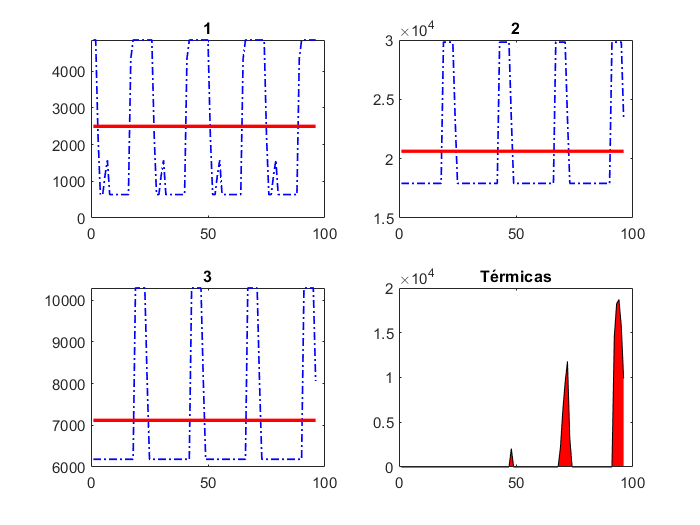

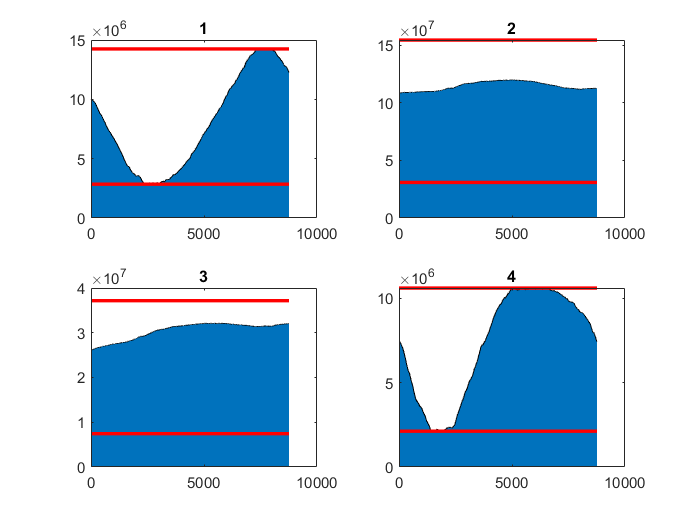

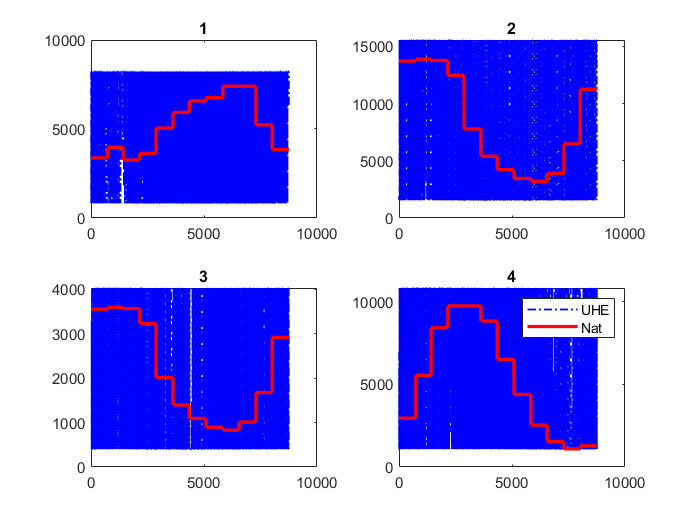

Sobra de energia nas hídricas


Sub1:2302542[MWh/a] Sub2:4190568[MWh/a] Sub3:6024353[MWh/a] Sub4:-0[MWh/a] 

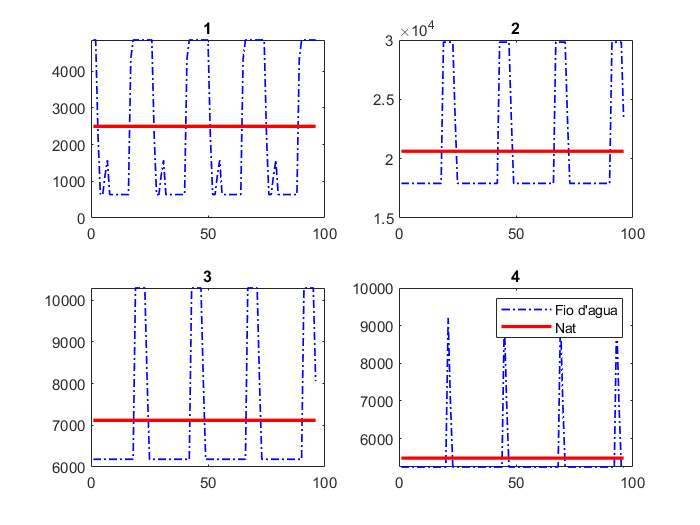

     1-2      1-3    1-4     2-3      2-4     3-4 
    ______    ___    ___    _____    _____    ____
    3490.9     0      0     16641    10926    3000


x = [];
x = result.x;
x = x/m;
t2 = nt*sub;
P = x(1:t2); % non-dispatchable renewable energy installed capacity

t1 = t2 + 1;
t2 = t2 + nTer*sub;
PTE = x(t1:t2); % non-renewables installed capacity

t1 = t2 + 1;
t2 = t2 + nUHEf;
x(t1:t2) = x(t1:t2)*m;
P_UHEf = x(t1:t2); % ReS installed capacity

t1 = t2 + 1;
t2 = t2 + nUHEfio;
x(t1:t2) = x(t1:t2)*m;
P_UHEfio = x(t1:t2); % RoR installed capacity

t1 = t2 + 1;
t2 = t2 + (sub*(sub-1)/2);
Pot_linha = x(t1:t2);
fluxo_linha = zeros(horas,sub^2); % transmission lines installed capacity
for t = 1:horas
    t1 = t2 + 1;
    t2 = t2 + sub^2;
    fluxo_linha(t,:) = x(t1:t2);
end
t1 = t2 + 1;
t2=t1;
Cap_def = x(t1); % Deficit capacity
deficit = sparse(horas,sub); % hourly deficit
for t = 1:sub
    t1 = t2 + 1;
    t2 = t2 + horas;
    deficit(:,t) = x(t1:t2);
end
for t = 1:sub
    t1 = t2 + 1;
    t2 = t2 + horas;
    curt(:,t) = x(t1:t2); % curtailment
end

for t = 1:sub
    t1 = t2 + 1;
    t2 = t2 + horas;
    UHEf(:,t) = x(t1:t2); % ReS Power generation
end

for t = 1:sub
    t1 = t2 + 1;
    t2 = t2 + horas;
    UHEfio(:,t) = x(t1:t2); % RoR Power generation
end
GT = [];
for t0 = 1:nTer
    for t = 1:sub
        t1 = t2 + 1;
        t2 = t2 + horas;
        GT.(termicas(t0))(:,t) = x(t1:t2); % Non-renewables Power generation
    end
end